clear all
close all
clc

% Load your data and perform necessary calculations
% (Assuming you have the 'assetsreturn' table with asset returns)
startdate = '1-jan-1980';

WORD_EQUITY_DEV = getMarketDataViaYahoo('^GSPC', startdate, datetime('today'), '1mo');
datevector = WORD_EQUITY_DEV.Date(1:end-1)

datevector = 463×1 datetime array
   1985-01-01
   1985-02-01
   1985-03-01
   1985-04-01
   1985-05-01
   1985-06-01
   1985-07-01
   1985-08-01
   1985-09-01
   1985-10-01
   1985-11-01
   1985-12-01
   1986-01-01
   1986-02-01
   1986-03-01
   1986-04-01
   1986-05-01
   1986-06-01
   1986-07-01
   1986-08-01
   1986-09-01
   1986-10-01
   1986-11-01
   1986-12-01
   1987-01-01
   1987-02-01
   1987-03-01
   1987-04-01
   1987-05-01
   1987-06-01



WORD_EQUITY_DEV = WORD_EQUITY_DEV(:,5)

WORD_EQUITY_DEV = 464×1 table
    Close 
    ______

    179.63
    181.18
    180.66
    179.83
    189.55
    191.85
    190.92
    188.63
    182.08
    189.82
    202.17
    211.28
    211.78
    226.92
     238.9
    235.52


assetsreturn = tick2ret(WORD_EQUITY_DEV)

assetsreturn = 463×1 table
      Close   
    __________

     0.0086288
      -0.00287
    -0.0045943
      0.054051
      0.012134
    -0.0048476
     -0.011995
     -0.034724
      0.042509
      0.065062
      0.045061
     0.0023665
      0.071489
      0.052794
     -0.014148
      0.050229



%%DEFINE THE WEIGHTS OF THE ASSETS
total_stock=[0; 0; 0 ;1];
MY_PORT=[0.1; 0.2; 0.2 ;0.5]

MY_PORT =     0.1000
    0.2000
    0.2000
    0.5000



weights = 1

weights = 1

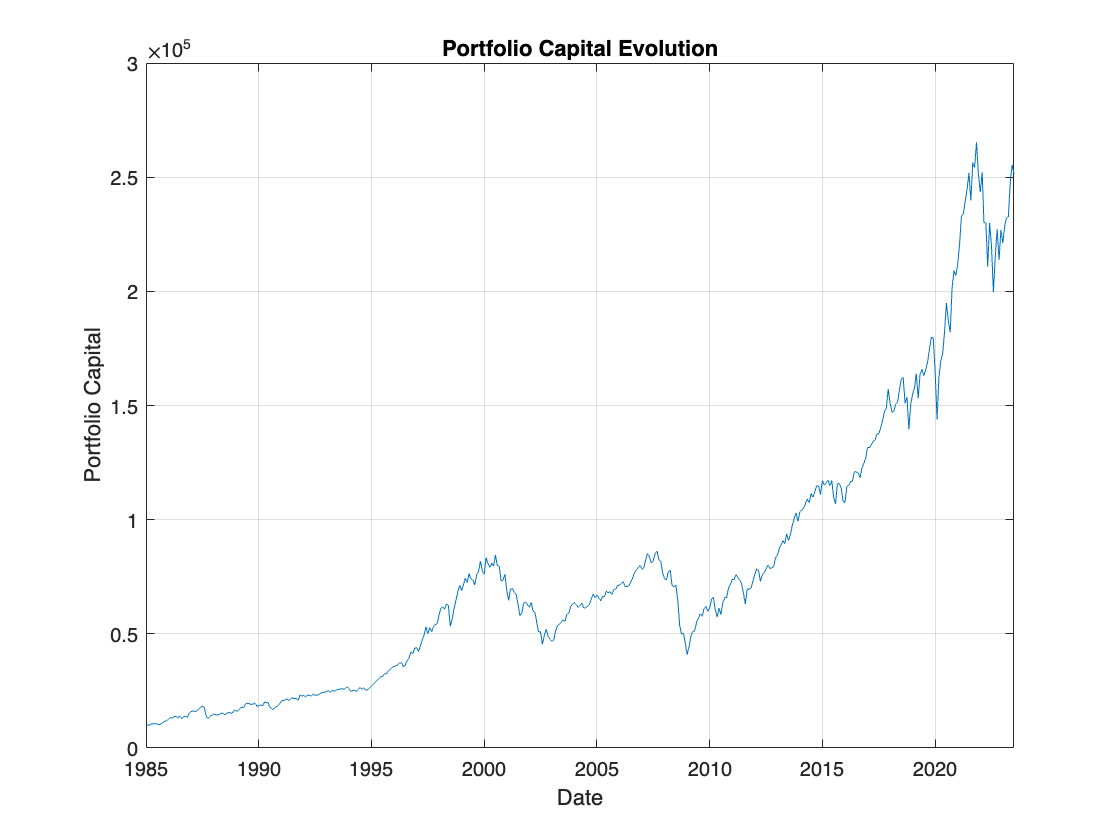


if round(sum(weights),2)== 1
    portReturn = sum(assetsreturn{:,:} .* weights, 2);
else
    disp("The portfolio does not reach 100%");
    return;
end
% Assuming you have already defined portReturn, the portfolio returns
initialCapital = 10000;
capitalevolution = cumprod(1 + portReturn) * initialCapital;  % Calculate capital evolution

% Plot the capital evolution
figure;
plot(datevector,capitalevolution);
title('Portfolio Capital Evolution');
xlabel('Date');
ylabel('Portfolio Capital');
grid on;


% Display final portfolio value
finalValue = capitalevolution(end);
fprintf('Initial Capital: $%.2f\n', initialCapital);

Initial Capital: $10000.00


fprintf('Final Portfolio Value: $%.2f\n', finalValue);

Final Portfolio Value: $251342.76


% Calculate summary metrics
finalValue = capitalevolution(end);
numYears = years(dateVector(end) - dateVector(2));

The end operator must be used within an array index expression.

CAGR = (finalValue / initialCapital)^(1/numYears) - 1;  % Compound Annual Growth Rate

% Calculate annualized return and standard deviation
annualizedReturn = (finalValue / initialCapital)^(1/numYears) - 1;
annualizedStdDev = std(portReturn) * sqrt(12);  % Assuming monthly data

% Calculate Sharpe Ratio
riskFreeRate = 0.009560;  % 10 y switzerland yield 
sharpeRatio = (annualizedReturn - riskFreeRate) / annualizedStdDev;

% Store summary metrics in a matrix
summaryMatrix = [CAGR, annualizedStdDev, sharpeRatio];

% Display the summary matrix
disp('Summary Matrix:');
disp(summaryMatrix);

% histogram of monthly return
histogram(portReturn);
title('Histogram of Portfolio Returns');
xlabel('Return');
ylabel('Frequency');

% Reshape monthly return data into a matrix with 12 columns representing each month
n_months = numel(portReturn);
n_years = floor(n_months / 12);
monthly_returns_matrix = reshape(portReturn, 12, n_years);

% Calculate annual returns for each year
annual_returns = prod(1 + monthly_returns_matrix) - 1;
annual_returns=annual_returns
% Create a histogram of annual returns
histogram(annual_returns,7);
title('Histogram of Annual Returns');
xlabel('Return');
ylabel('Frequency');

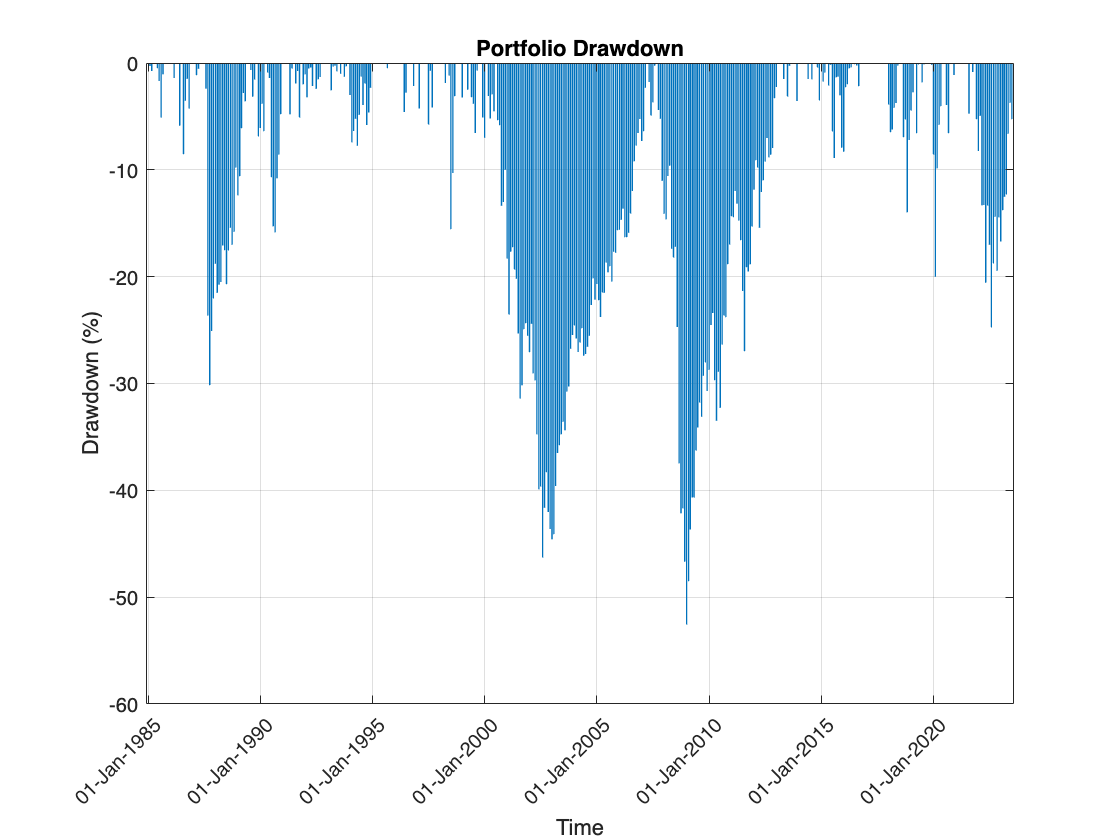

%% DRAWDOWN
% Calculate the cumulative portfolio return
cumulativePortfolioReturn = cumprod(1 + portReturn);

% Initialize variables for drawdown calculation
numPeriods = length(cumulativePortfolioReturn);
drawdowns = zeros(numPeriods, 1);
peakIdx = 1;
maxDrawdown = 0;  % Initialize the maximum drawdown

% Calculate drawdowns and identify the maximum drawdown
for troughIdx = 1:numPeriods
    if cumulativePortfolioReturn(troughIdx) > cumulativePortfolioReturn(peakIdx)
        peakIdx = troughIdx;
    end
    
    % Calculate drawdown at the current trough
    drawdown = ((cumulativePortfolioReturn(troughIdx) - cumulativePortfolioReturn(peakIdx)) ...
        / cumulativePortfolioReturn(peakIdx));
    
    % Update the maximum drawdown if needed
    maxDrawdown = min(maxDrawdown, drawdown);
    
    drawdowns(troughIdx) = drawdown;
end

% Get the dates for x-axis

% Create a bar plot for drawdowns
figure;
bar(datevector, drawdowns * 100);
xlabel('Time');
ylabel('Drawdown (%)');
title('Portfolio Drawdown');
xtickangle(45);
xtickformat('dd-MMM-yyyy'); % Format dates for better readability
grid on;


fprintf('Maximum Drawdown: %.2f%%\n', maxDrawdown * 100);

Maximum Drawdown: -52.56%


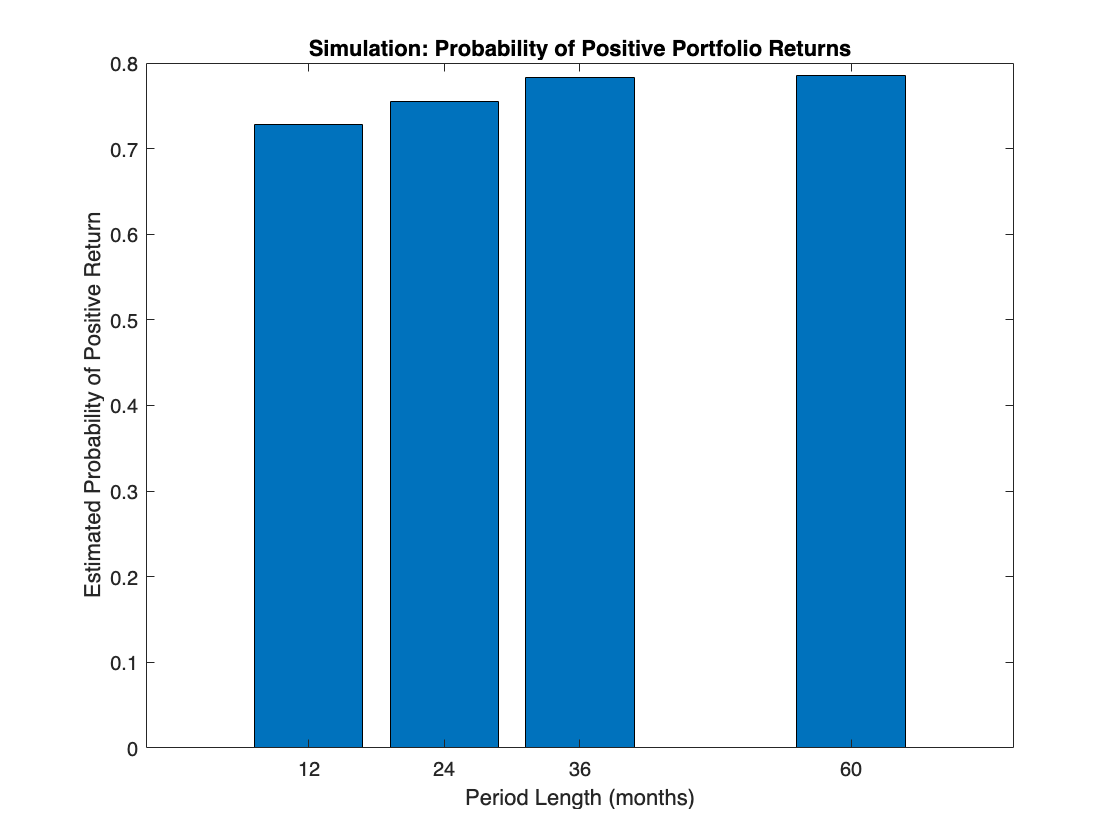

%%  INVESTMENT HORIZON   
% Define simulation parameters
periodLengths = [12, 24, 36, 60]; % Period lengths in months
numIterations = 1000; % Number of simulation iterations
startDate = datetime('1-jan-1990'); % Start date of your data (adjusted)
endDate = datetime('2020-08-01'); % End date of your data

% Calculate the number of months between start and end dates
numMonths = calmonths(between(startDate, endDate));

% Initialize a matrix to store the simulation results
simulationResults = zeros(numIterations, length(periodLengths));


% Loop through each period length
for i = 1:length(periodLengths)
    periodLength = periodLengths(i);
    
    % Loop through each simulation iteration
    for j = 1:numIterations
        % Generate a synthetic sample of portfolio returns for the given period
        startIndex = randi(numMonths - periodLength + 1);
        endIndex = startIndex + periodLength - 1;
        
        historicalReturns = portReturn(startIndex:endIndex);
        
        % Generate synthetic samples based on the historical distribution
        syntheticReturns = randsample(historicalReturns, periodLength, true);
        
        % Calculate the cumulative return for the synthetic sample
        cumulativeReturn = cumprod(1 + syntheticReturns / 100) - 1;
        
        % Check if the cumulative return is positive
        simulationResults(j, i) = cumulativeReturn(end) > 0;
    end
end


% Calculate the estimated probabilities of positive returns for each period length
estimatedProbabilities = mean(simulationResults);

% Display the results
bar(periodLengths, estimatedProbabilities);
xlabel('Period Length (months)');
ylabel('Estimated Probability of Positive Return');
title('Simulation: Probability of Positive Portfolio Returns');

%% VALUE AT RISK MC SIMULATION
initialValue = 10000; % Initial value of the asset or portfolio
confidenceLevel = 0.95; % 99% confidence level
timeHorizonMonths = 12; % Time horizon in months

% Number of simulation scenarios
numScenarios = 1000;
numYears=33

numYears = 33


% Generate random scenarios by resampling from historical data
numReturns = numel(portReturn);
simulatedReturns = datasample(portReturn, numScenarios * timeHorizonMonths, 'Replace', true);
simulatedReturns = reshape(simulatedReturns, numScenarios, timeHorizonMonths);

% Calculate future values for each scenario
futureValues = initialValue * cumprod(1 + simulatedReturns, 2);

% Calculate the maximum loss for each scenario over the year
maxLoss = initialValue - min(futureValues, [], 2);

% Sort the maximum losses in ascending order
sortedMaxLosses = sort(maxLoss, 1);

% Calculate VaR at the specified confidence level in dollars
varIndex = round((1 - confidenceLevel) * numScenarios);
varValue = sortedMaxLosses(varIndex);

% Calculate VaR as a percentage of the initial investment
varPercentage = (varValue / initialValue) * 100;

% Display the results
fprintf('VaR at %.2f%% confidence level for a %d-month horizon:\n', confidenceLevel * 100, timeHorizonMonths);

VaR at 95.00% confidence level for a 12-month horizon:


fprintf('Maximum loss in dollars: $%.2f\n', varValue);

Maximum loss in dollars: $-537.53


fprintf('Maximum loss as a percentage of initial investment: %.2f%%\n', varPercentage);

Maximum loss as a percentage of initial investment: -5.38%


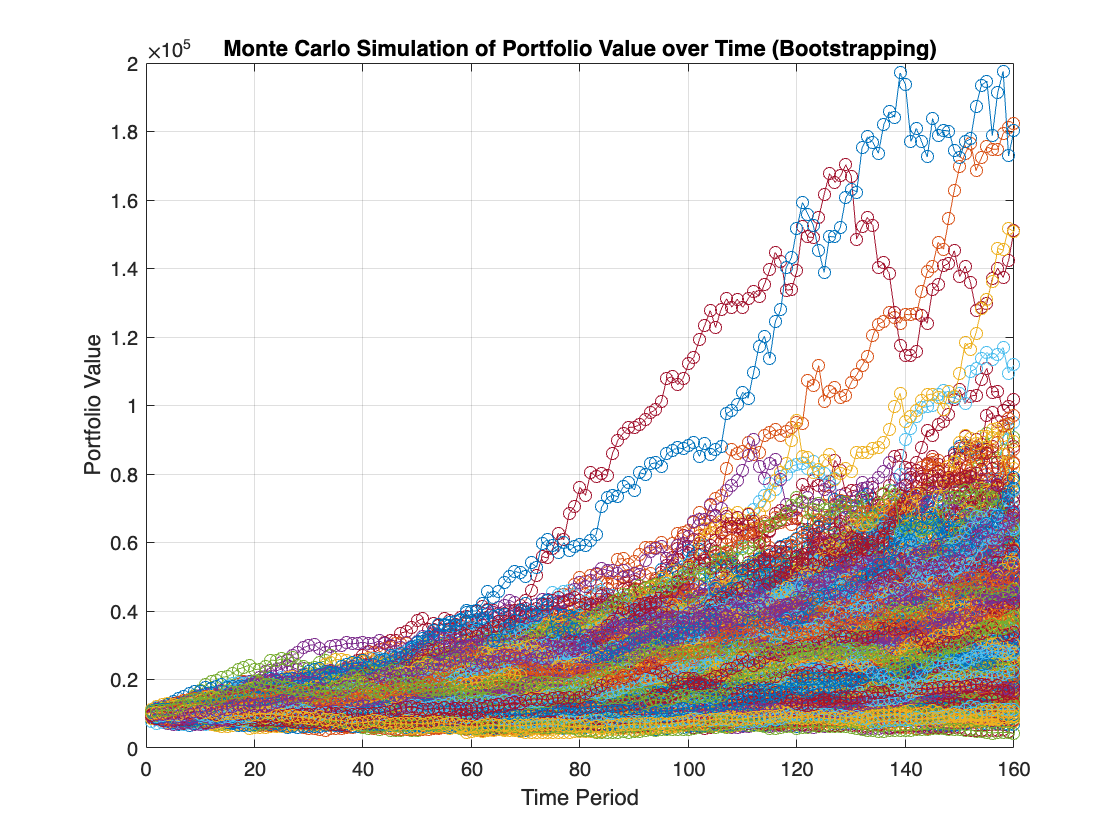

%% Forecasts

% Parameters
numSimulations = 600;      % Number of simulations
numPeriods = 160;            % Number of time periods
initialInvestment = 10000;  % Initial investment amount

% Initialize a matrix to store portfolio values for each simulation and period
portfolioValues = zeros(numSimulations, numPeriods);

% Perform bootstrap simulations
for i = 1:numSimulations
    % Generate random indices for bootstrapping
    indices = randi(length(portReturn), numPeriods, 1);
    simulatedReturns = portReturn(indices);
    
    % Calculate portfolio values over time for each simulation
    portfolioValue = initialInvestment;
    for j = 1:numPeriods
        portfolioValue = portfolioValue * (1 + simulatedReturns(j));
        portfolioValues(i, j) = portfolioValue;
    end
end

% Plot the results
figure;
for i = 1:numSimulations
    plot(1:numPeriods, portfolioValues(i, :), '-o');
    hold on;
end
xlabel('Time Period');
ylabel('Portfolio Value');
title('Monte Carlo Simulation of Portfolio Value over Time (Bootstrapping)');
grid on;
hold off;

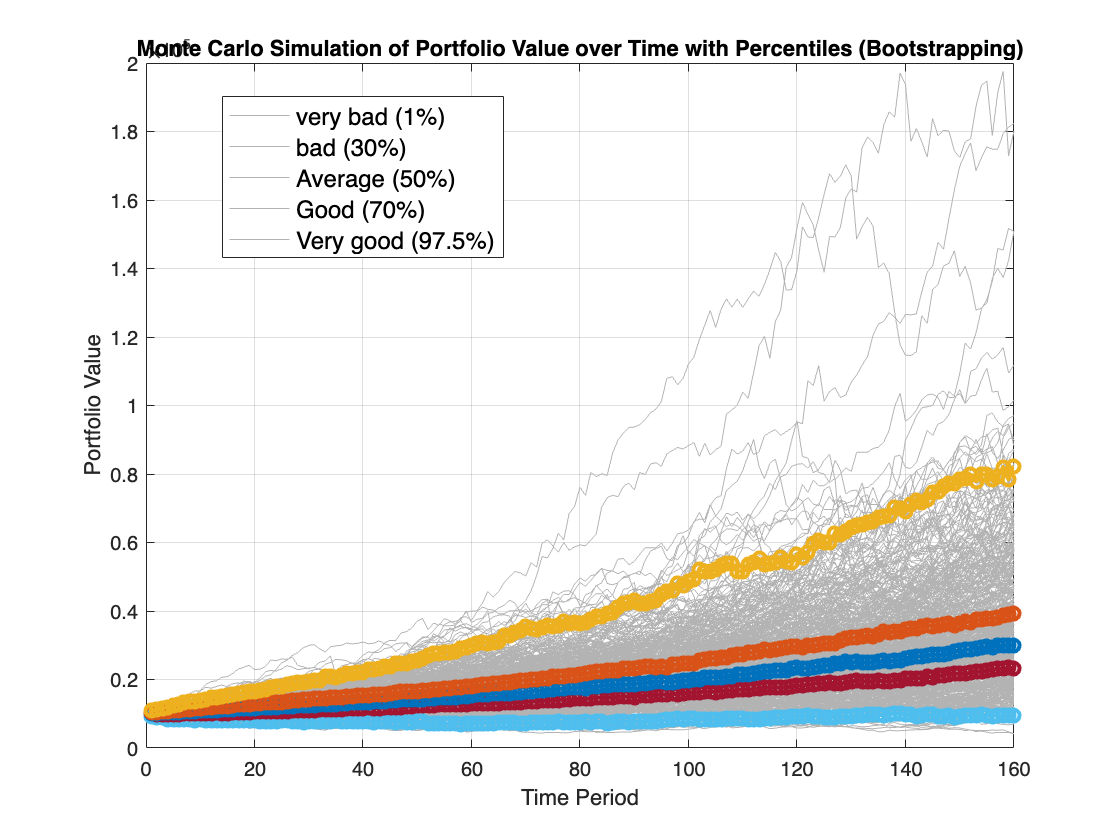


% Calculate and plot percentiles
percentiles = [2.5, 30, 50.0, 70, 97.5];
portfolioPercentiles = quantile(portfolioValues, percentiles / 100);

figure;
for i = 1:numSimulations
    plot(1:numPeriods, portfolioValues(i, :), 'Color', [0.7 0.7 0.7]);
    hold on;
end
plot(1:numPeriods, portfolioPercentiles, '-o', 'LineWidth', 2);
hold off;

legend({'very bad (1%)', 'bad (30%)', 'Average (50%)', 'Good (70%)', 'Very good (97.5%)'}, 'Location', 'Best', 'FontSize', 12);
xlabel('Time Period');
ylabel('Portfolio Value');
title('Monte Carlo Simulation of Portfolio Value over Time with Percentiles (Bootstrapping)');
grid on;

## CORRELATIONS

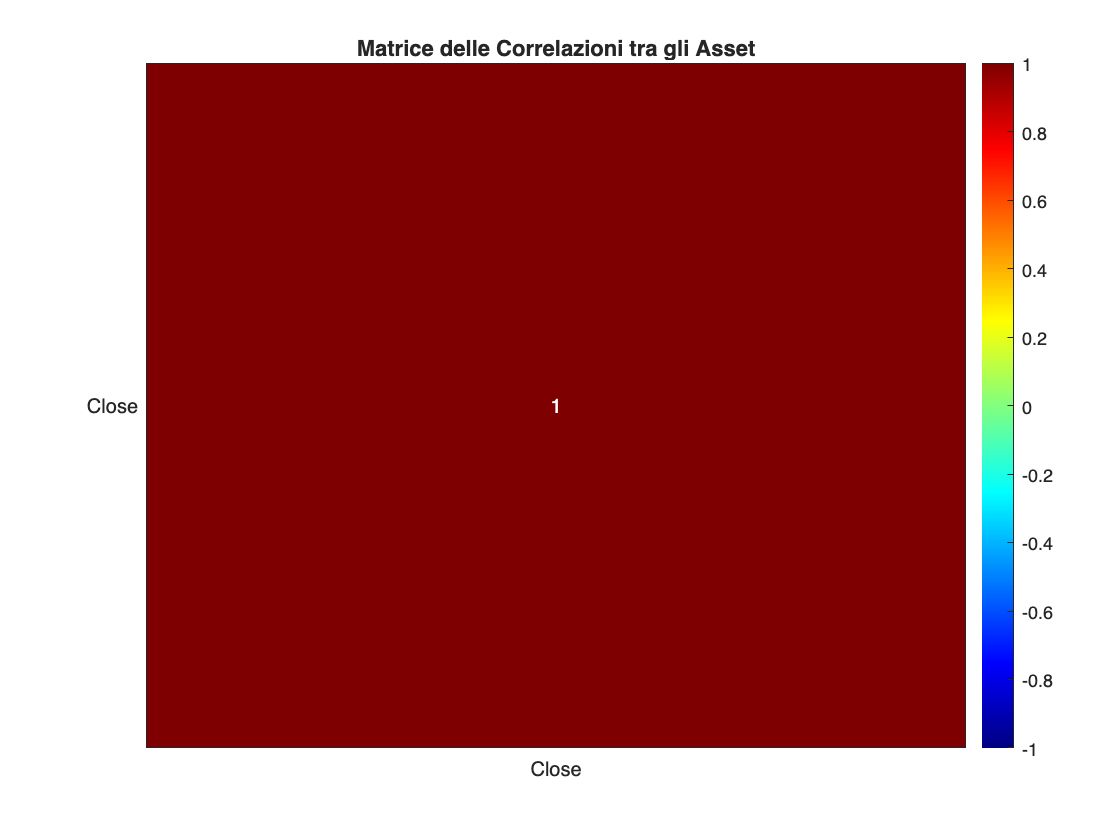

% Calcola la matrice delle correlazioni tra gli asset
correlationMatrix = corrcoef(assetsreturn{:,:});

% Nomi degli asset per l'etichettatura degli assi
assetNames = assetsreturn.Properties.VariableNames;

% Creazione della heatmap
figure;
heatmap(assetNames, assetNames, correlationMatrix, 'Colormap', jet, 'ColorLimits', [-1 1], ...
    'Title', 'Matrice delle Correlazioni tra gli Asset');

## DINAMIC CORRELATIONS

nAssets = 1

weights = 1

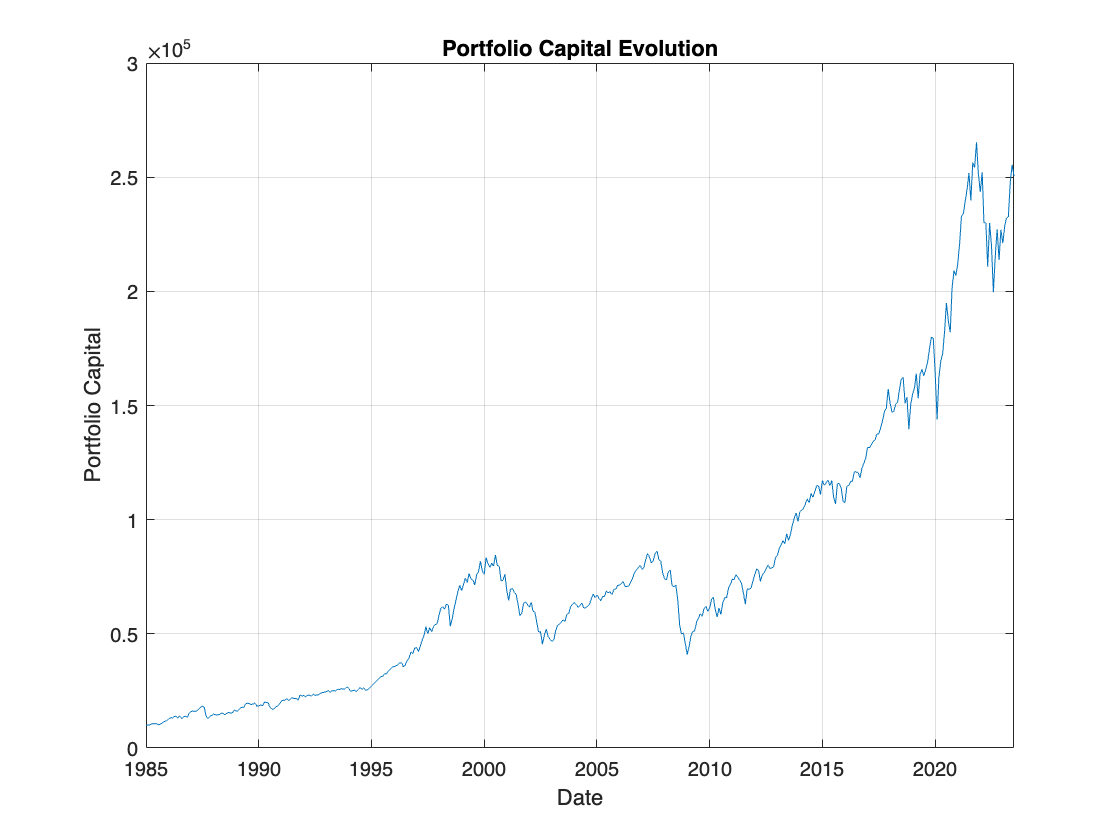

Initial Capital: $10000.00


Final Portfolio Value: $250383.00


The end operator must be used within an array index expression.

Unable to resolve the name 'assetsreturn.Properties.RowTimes'.

numYears = 12.9147

VaR at 95.00% confidence level for a 12-month horizon:


Maximum loss in dollars: $-65.13


Maximum loss as a percentage of initial investment: -0.65%


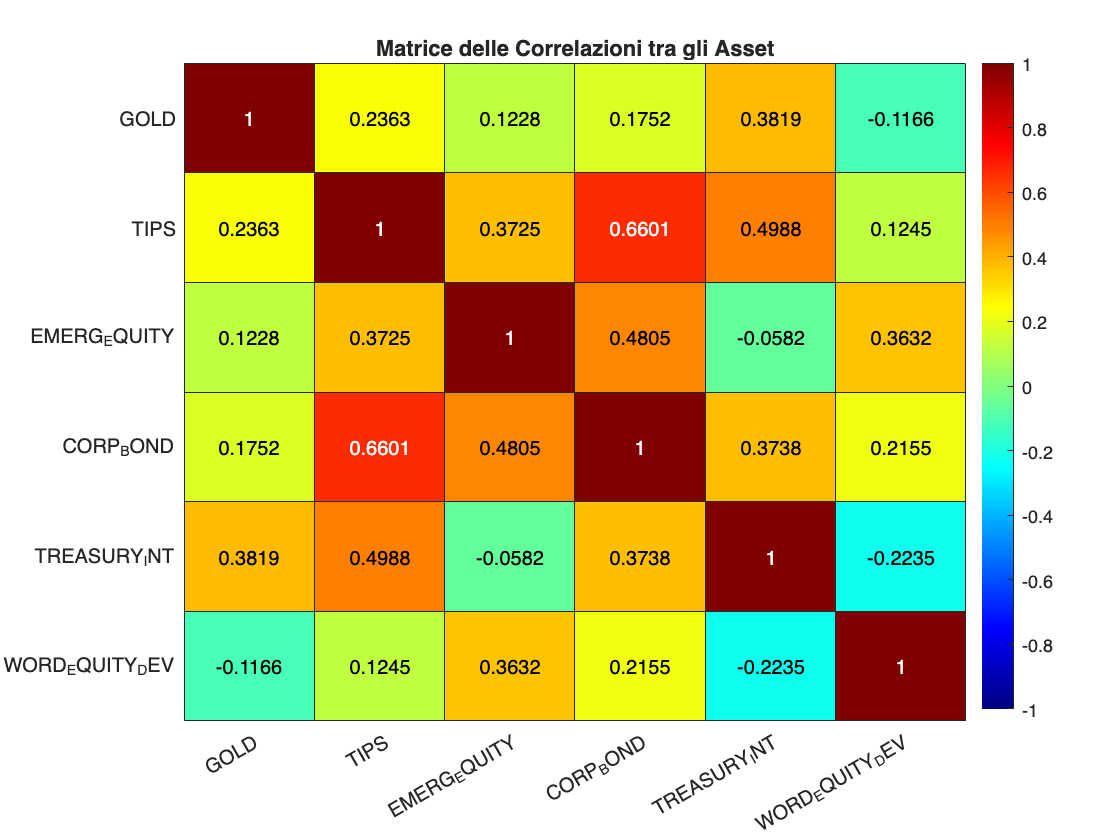

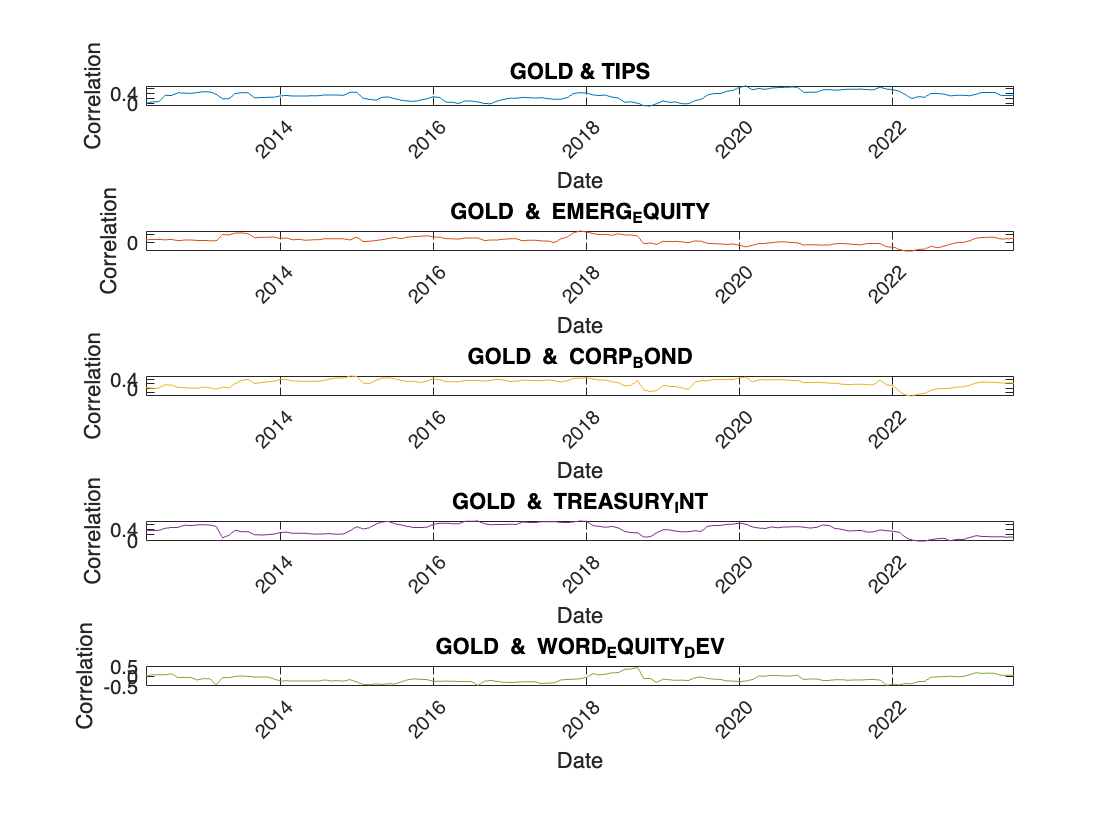

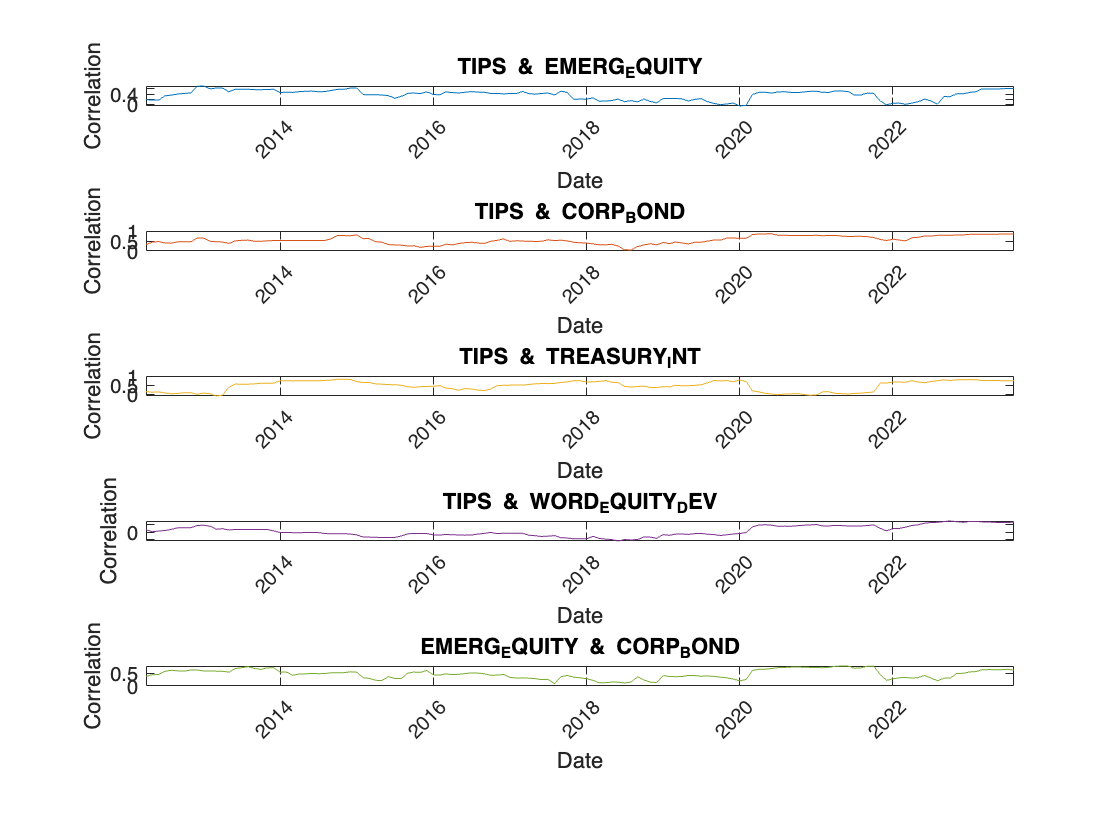

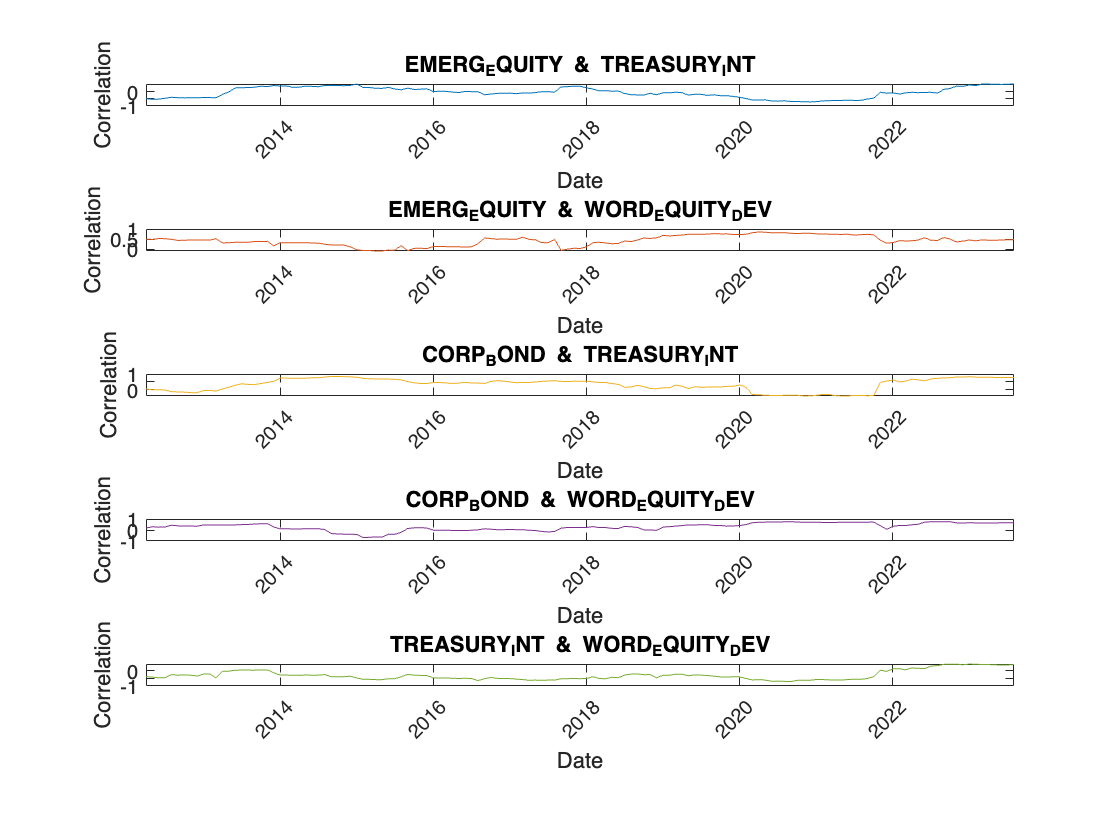

p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: []
       UpperBound: []
      LowerBudget: []
      UpperBudget: []
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [7×1 double]
       UpperBound: []
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: [7×1 categorical]


n = 12

backtester =   backtestEngine with properties:

               Strategies: [1×4 backtestStrategy]
             RiskFreeRate: 0.0200
           CashBorrowRate: 0
          RatesConvention: "Annualized"
                    Basis: 0
    InitialPortfolioValue: 10000
           DateAdjustment: "Previous"
                NumAssets: []
                  Returns: []
                Positions: []
                 Turnover: []
                  BuyCost: []
                 SellCost: []
                     Fees: []


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: []
       UpperBound: []
      LowerBudget: []
      UpperBudget: []
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [7×1 double]
       UpperBound: []
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: [7×1 categorical]


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: []
       UpperBound: []
      LowerBudget: []
      UpperBudget: []
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [7×1 double]
       UpperBound: []
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: [7×1 categorical]


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: []
       UpperBound: []
      LowerBudget: []
      UpperBudget: []
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [7×1 double]
       UpperBound: []
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: [7×1 categorical]


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: []
       UpperBound: []
      LowerBudget: []
      UpperBudget: []
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [7×1 double]
       UpperBound: []
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: [7×1 categorical]


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: []
       UpperBound: []
      LowerBudget: []
      UpperBudget: []
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [7×1 double]
       UpperBound: []
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: [7×1 categorical]


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: []
       UpperBound: []
      LowerBudget: []
      UpperBudget: []
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [7×1 double]
       UpperBound: []
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: [7×1 categorical]


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: []
       UpperBound: []
      LowerBudget: []
      UpperBudget: []
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [7×1 double]
       UpperBound: []
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: [7×1 categorical]


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: []
       UpperBound: []
      LowerBudget: []
      UpperBudget: []
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [7×1 double]
       UpperBound: []
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: [7×1 categorical]


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: []
       UpperBound: []
      LowerBudget: []
      UpperBudget: []
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [7×1 double]
       UpperBound: []
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: [7×1 categorical]


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: []
       UpperBound: []
      LowerBudget: []
      UpperBudget: []
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [7×1 double]
       UpperBound: []
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: [7×1 categorical]


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: []
       UpperBound: []
      LowerBudget: []
      UpperBudget: []
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [7×1 double]
       UpperBound: []
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: [7×1 categorical]


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: []
       UpperBound: []
      LowerBudget: []
      UpperBudget: []
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [7×1 double]
       UpperBound: []
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: [7×1 categorical]


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: []
       UpperBound: []
      LowerBudget: []
      UpperBudget: []
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: []
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 7
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [7×1 double]
       UpperBound: []
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: [7×1 categorical]


backtester =   backtestEngine with properties:

               Strategies: [1×4 backtestStrategy]
             RiskFreeRate: 0.0200
           CashBorrowRate: 0
          RatesConvention: "Annualized"
                    Basis: 0
    InitialPortfolioValue: 10000
           DateAdjustment: "Previous"
                NumAssets: 7
                  Returns: [156×4 timetable]
                Positions: [1×1 struct]
                 Turnover: [156×4 timetable]
                  BuyCost: [156×4 timetable]
                 SellCost: [156×4 timetable]
                     Fees: [1×1 struct]


Execution of script sharpe as a function is not supported:
/Users/carlocascini/Desktop/MARKOWITZ/sharpe.mlx

Error in backtestEngine/summary (line 811)
            sharpeRatio     = sharpe(dailyReturns,obj.PerStepCashRates);

windowSize = 20; % Dimensione della finestra mobile

numAssets = width(assetsreturn); % Numero di asset
numWindows = height(assetsreturn) - windowSize + 1; % Numero di finestre
numCorrelations = numAssets * (numAssets - 1) / 2; % Numero totale di correlazioni

rollingCorrelations = zeros(numWindows, numCorrelations); 

for i = 1:numWindows
    windowData = assetsreturn(i:i+windowSize-1, :); % Dati nella finestra mobile
    windowCorrelations = corrcoef(table2array(windowData)); % Calcola le correlazioni
    
    % Estrai le correlazioni tra coppie di asset
    counter = 1;
    for asset1 = 1:numAssets
        for asset2 = asset1+1:numAssets
            rollingCorrelations(i, counter) = windowCorrelations(asset1, asset2);
            counter = counter + 1;
        end
    end
end

% Estrai le date corrispondenti alle finestre mobili
windowDates = assetsreturn.Properties.RowTimes(end - numWindows + 1:end);

% Organizza i grafici in 3 figure, ognuna con 5 grafici
numFigures = 3;
numGraphsPerFigure = 2;
colors = lines(numGraphsPerFigure); % Generate distinct colors for each subplot

for figureIndex = 1:numFigures
    figure;
    
    for graphIndex = 1:numGraphsPerFigure
        idx = (figureIndex - 1) * numGraphsPerFigure + graphIndex;
        subplot(numGraphsPerFigure, 1, graphIndex);
        plot(windowDates, rollingCorrelations(:, idx), 'Color', colors(graphIndex, :)); % Set subplot color
        
        % Calcola gli indici delle coppie di asset
        assetPairs = nchoosek(1:numAssets, 2);
        assetIndex1 = assetPairs(idx, 1);
        assetIndex2 = assetPairs(idx, 2);
        
        % Aggiungi etichette delle variabili
        assetNames = assetsreturn.Properties.VariableNames;
        title([assetNames{assetIndex1}, ' & ', assetNames{assetIndex2}]);
        
        xlabel('Date');
        ylabel('Correlation');
        xtickangle(45); % Rotate x-axis labels for better visibility
        hold off
    end
end